# Nonlinear system identification of the two-tank problem

## The Input-Output Data Set

In this example, the data variables stored in the `twotankdata.mat` file will be used. It contains 3000 input-output data samples of a two-tank system generated using a sample time of 0.2 seconds. The input u(t) is the voltage [V] applied to a pump, which generates an inflow to the upper tank. A rather small hole at the bottom of this upper tank yields an outflow that goes into the lower tank, and the output y(t) of the two tank system is then the liquid level [m] of the lower tank. We create an IDDATA object `z` to encapsulate the loaded data:

This data set is also used in the nonlinear grey box example "Two Tank System: C MEX-File Modeling of Time-Continuous SISO System" where physical equations describing the system are assumed. This example is about black box models, thus no knowledge of the actual physical laws is assumed.

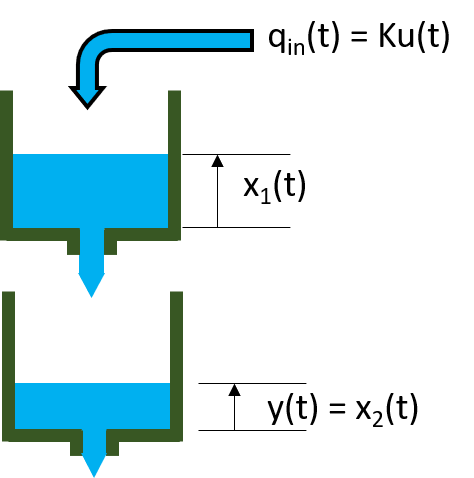

clear; close all;
load twotankdata
z = iddata(y, u, 0.2, 'Name', 'Two tank system');

## Splitting the Data and Plotting

Split this data set into 3 subsets of equal size, each containing 1000 samples.

We shall estimate models with `z1`, and evaluate them on `z2` and `z3`. `z1` is similar to `z2`, but not `z3`. Therefore in some sense, `z2` would help us evaluate the interpolation ability of the models, while `z3` would help us evaluate their extrapolation ability.

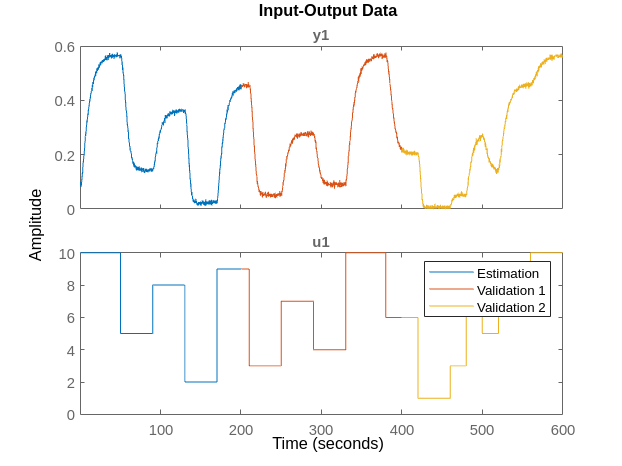

z1 = z(1:1000);
z2 = z(1001:2000);
z3 = z(2001:3000);
plot(z1,z2,z3)
legend('Estimation','Validation 1', 'Validation 2')

## NLARX Model (Linear regressors + Linear output function + Offset)

### Model Structure

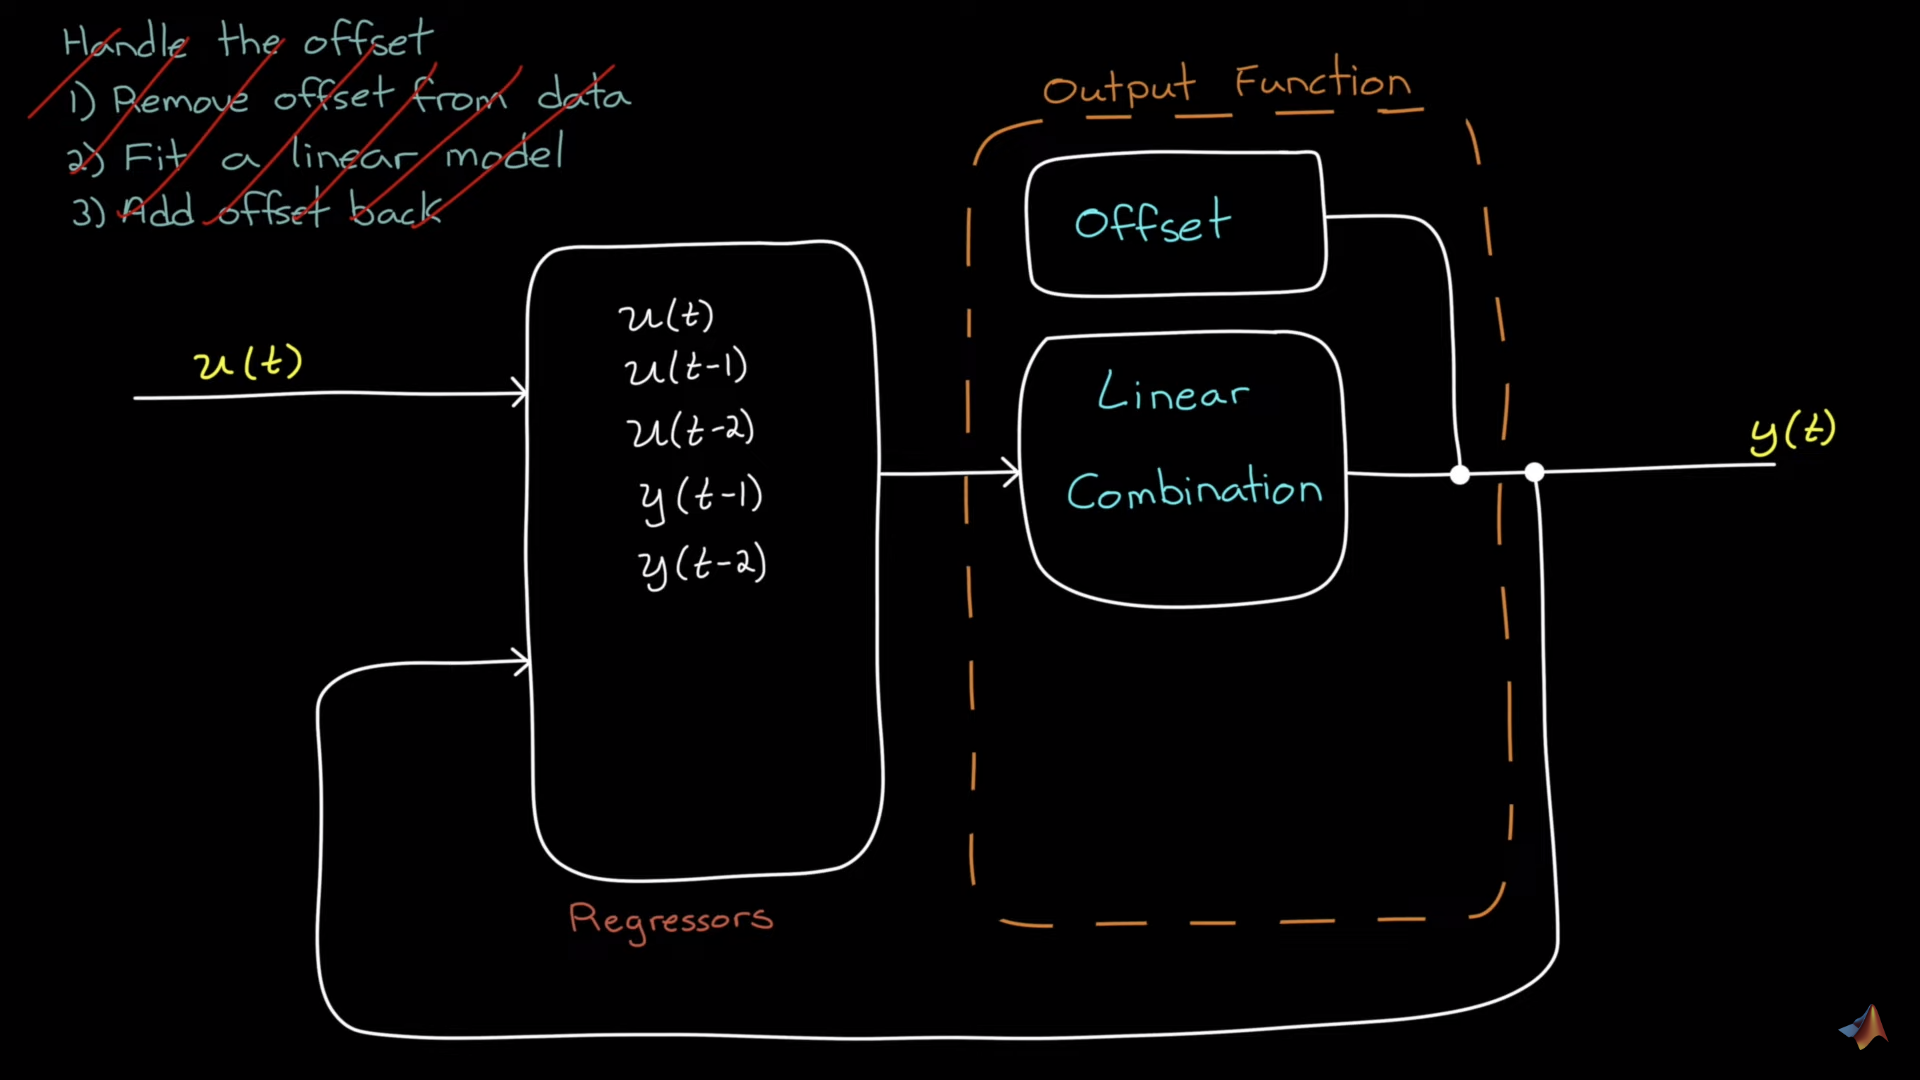

names = [z1.OutputName; z1.InputName];
% Define linear regressors
%L = [
% y1(t-1);
% y1(t-2);
% u1(t);
% u1(t-1);
% u1(t-2)]
L = linearRegressor(names, {1:2, 0:2})

L = Linear regressors in variables y1, u1
       Variables: {'y1'  'u1'}
            Lags: {[1 2]  [0 1 2]}
     UseAbsolute: [0 0]
    TimeVariable: 't'

  Regressors described by this set

### Fit the model to the data

mw1 = nlarx(z1, L, idLinear);

## Model validation

Review the model

NLFcn = mw1.OutputFcn

NLFcn = Linear Function
Inputs: y1(t-1), y1(t-2), u1(t), u1(t-1), u1(t-2)
Output: y1(t)

 Nonlinear Function: Linear with offset
 Linear Function: initialized to [0.135 0.021 -0.0115 0.114 -0.000386]
 Output Offset: initialized to -4.52e-17

       Inputs: {'y1(t-1)'  'y1(t-2)'  'u1(t)'  'u1(t-1)'  'u1(t-2)'}
      Outputs: {'y1(t)'}
    LinearFcn: 'Linear function parameters'
       Offset: 'Offset

Examine the result by comparing the response of the model `mw1` to the measured output in the dataset `z1`.

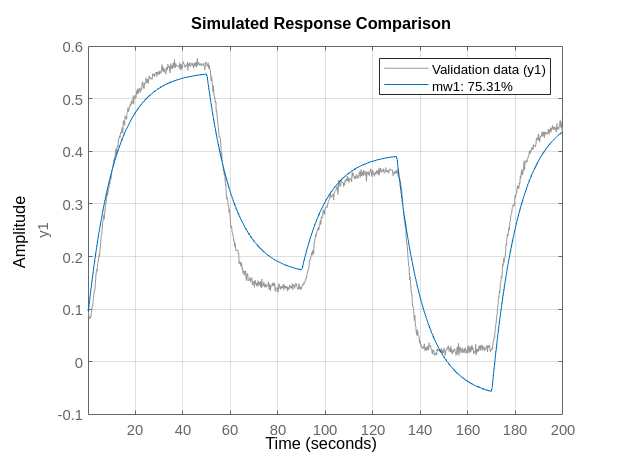

% training set
compare(z1,mw1);
grid on

Examine the result by comparing the response of the model `mw1` to the validation dataset `z2`.

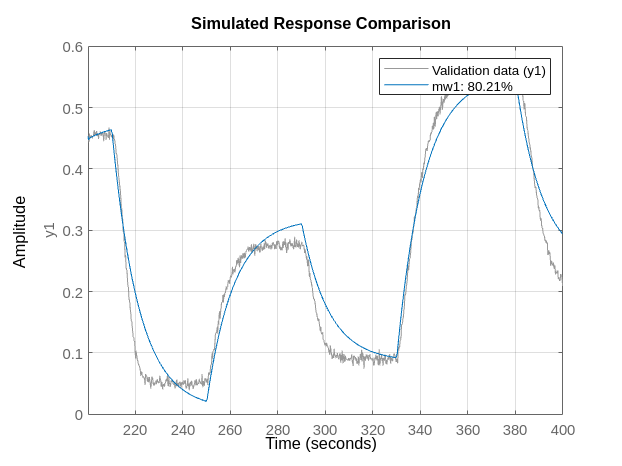

% validation set
compare(z2,mw1);
grid on

## NLARX Model (Nonlinear regressors + Linear output function + Offset)

### Intuitively add a nonlinear regressor

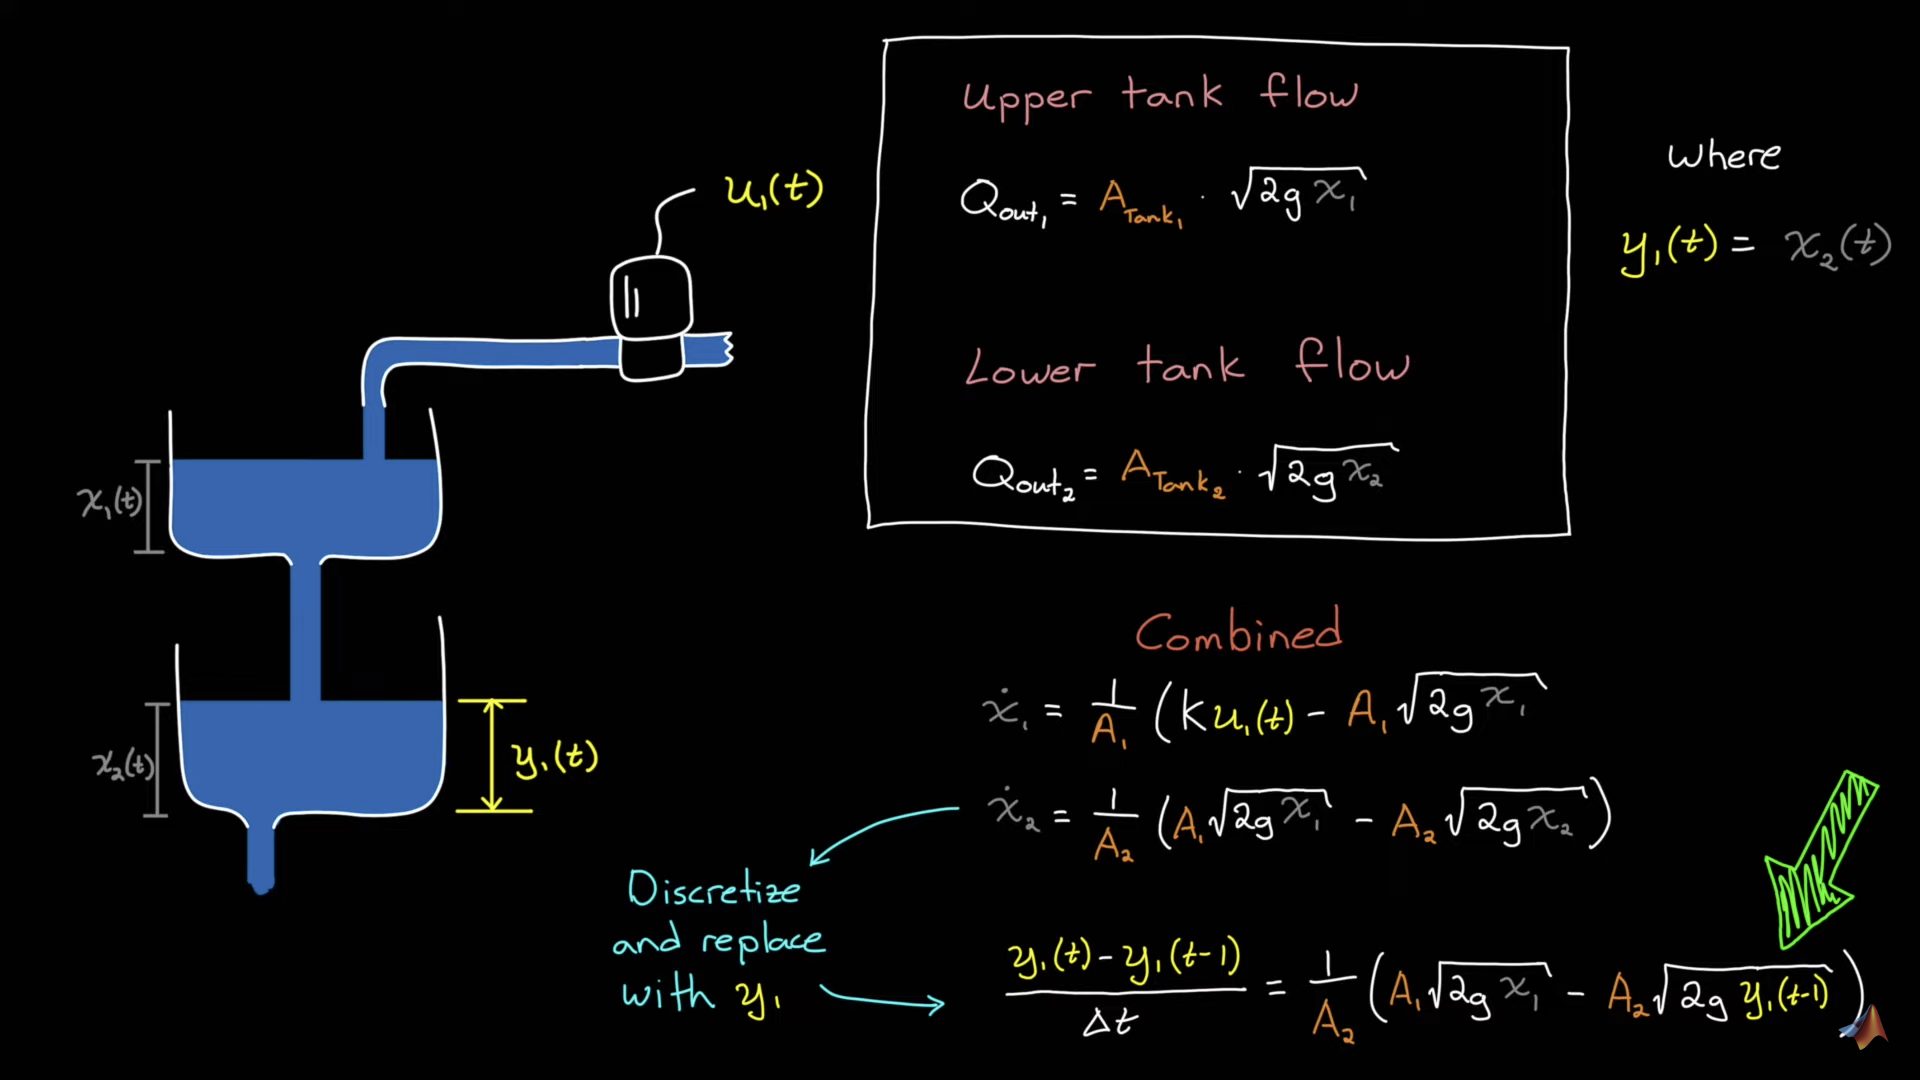

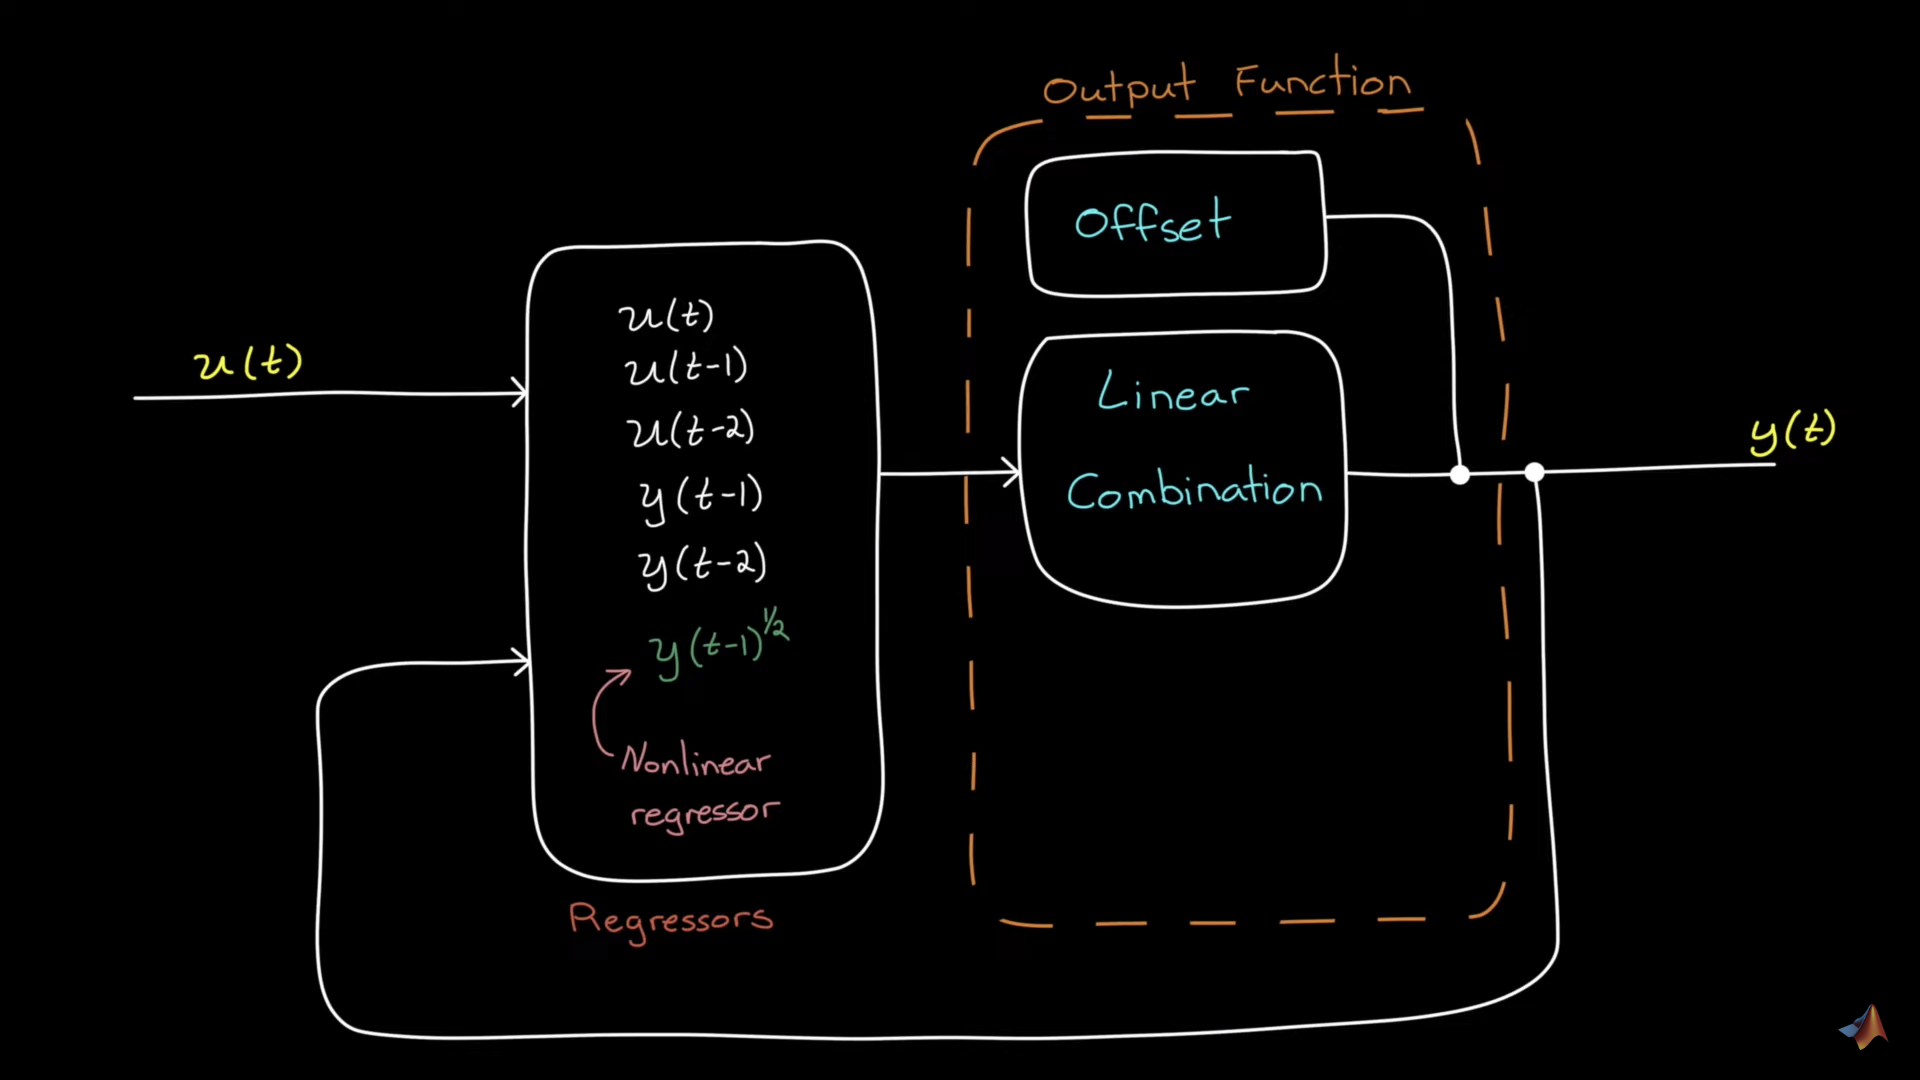

### Define the custom regressor

C = customRegressor({'y1'},{1},@(y)sqrt(y));
R = [L;C];

### Fit the model to the data

mw2 = nlarx(z1, R, idLinear);

The regressors of the IDNLARX model can be viewed using the GETREG command. The regressors are made from `mw2.InputName`, `mw2.OutputName` and time delays.

getreg(mw2)

ans = 6×1 cell array
    {'y1(t-1)'      }
    {'y1(t-2)'      }
    {'u1(t)'        }
    {'u1(t-1)'      }
    {'u1(t-2)'      }
    {'sqrt(y1(t-1))'}


## Model validation

Review the model

NLFcn2 = mw2.OutputFcn

NLFcn2 = Linear Function
Inputs: y1(t-1), y1(t-2), u1(t), u1(t-1), u1(t-2), sqrt(y1(t-1))
Output: y1(t)

 Nonlinear Function: Linear with offset
 Linear Function: initialized to [0.136 0.0249 0.0986 0.0544 0.013 -0.000432]
 Output Offset: initialized to -6.13e-17

       Inputs: {'y1(t-1)'  'y1(t-2)'  'u1(t)'  'u1(t-1)'  'u1(t-2)'  'sqrt(y1(t-1))'}
      Outputs: {'y1(t)'}
    LinearFcn: 'Linear function parameters'
       Offset: '

Examine the result by comparing the response of the model `mw2` to the measured output in the dataset `z1`.

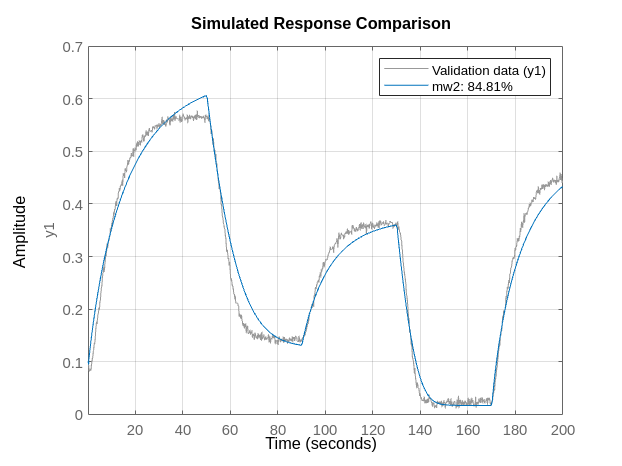

% training set
compare(z1,mw2);
grid on

Examine the result by comparing the response of the model `mw2` to the validation dataset `z2`.

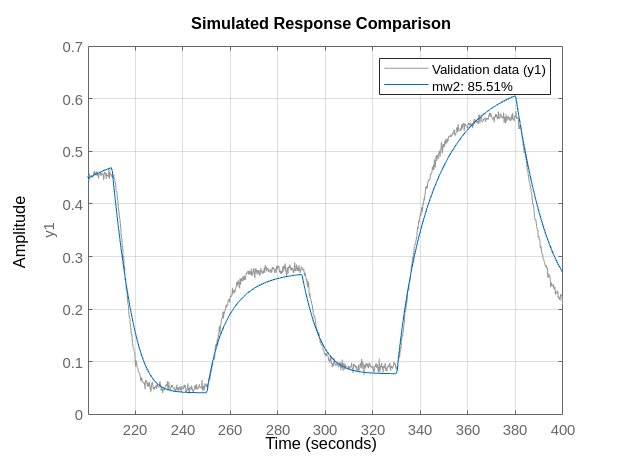

% validation set
compare(z2,mw2);
grid on

Examine the result by comparing the response of the model `mw2` to the validation dataset `z3`.

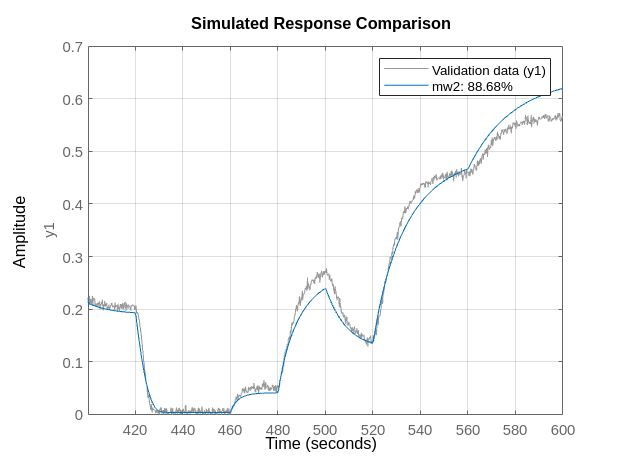

% validation set
compare(z3,mw2);
grid on

## NLARX Model (Nonlinear regressors + Linear/Nonlinear output function + Offset)

### Model Structure

## 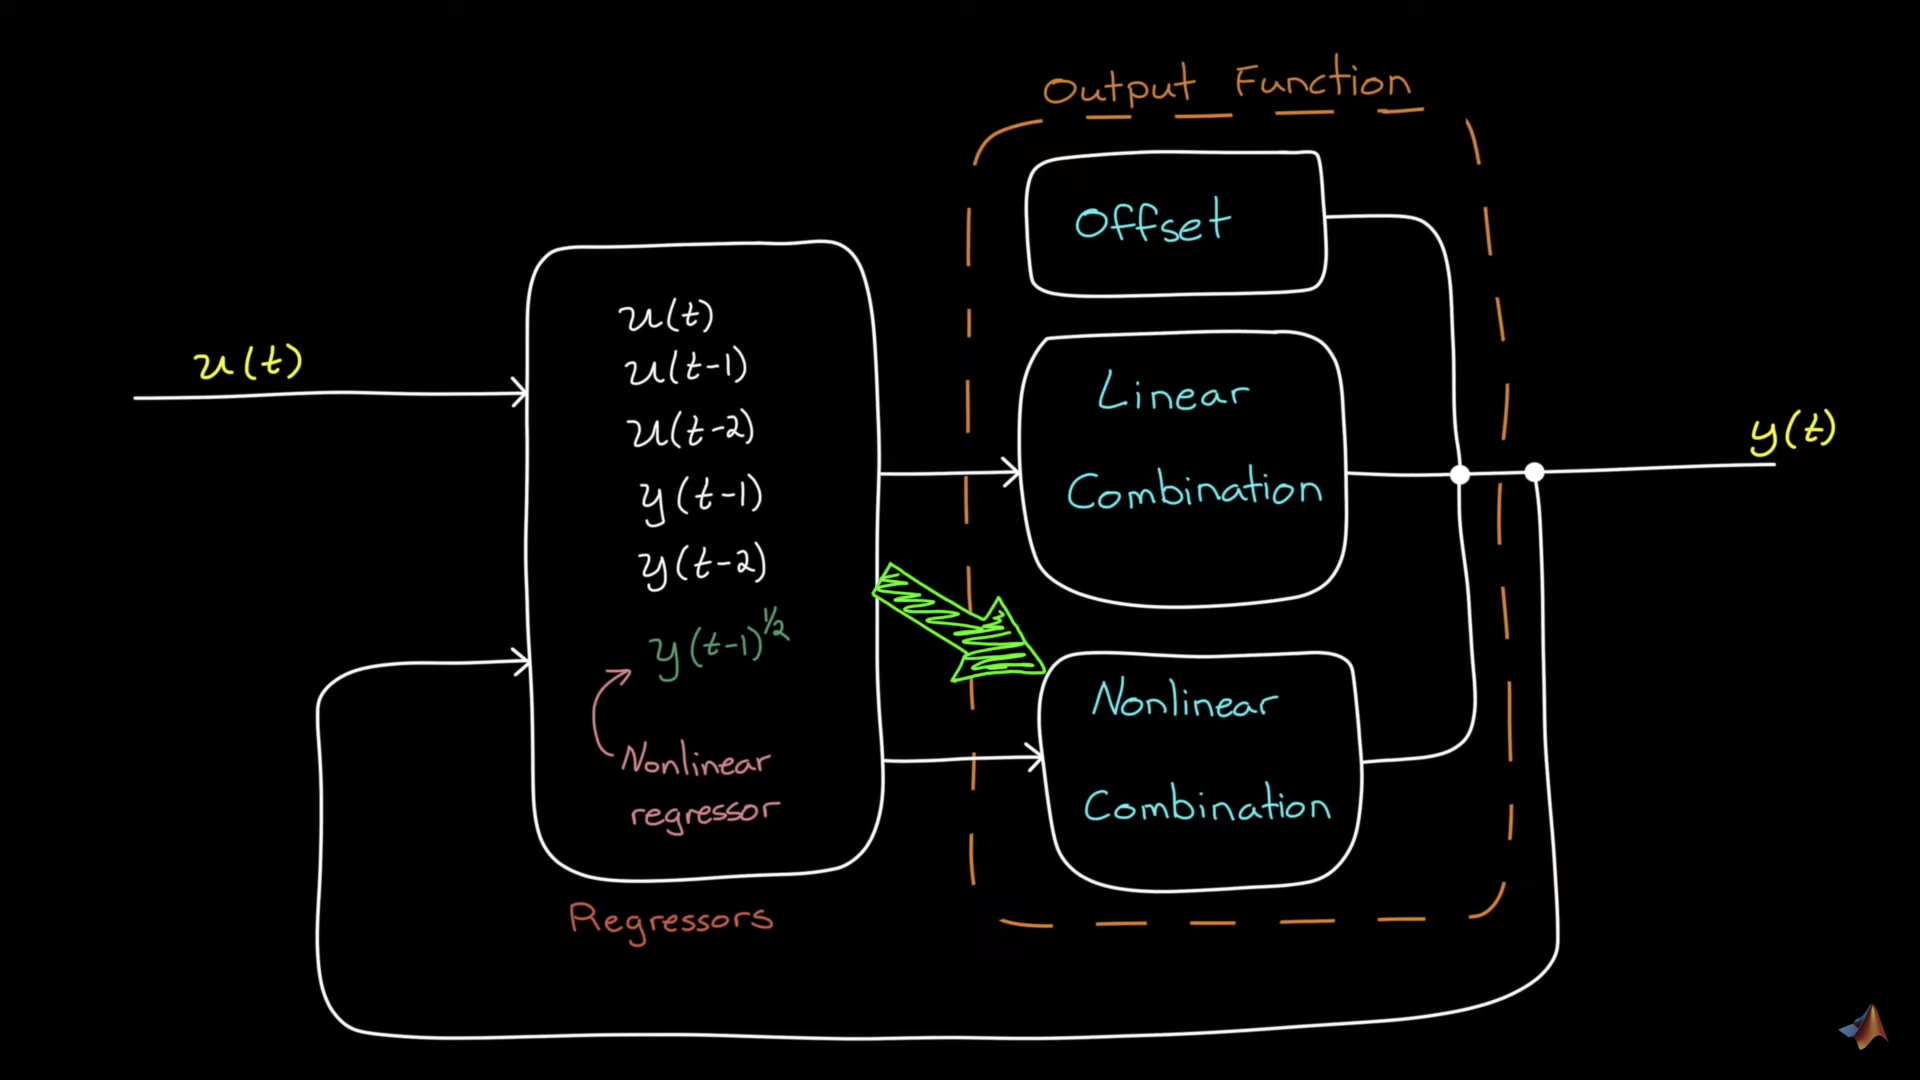

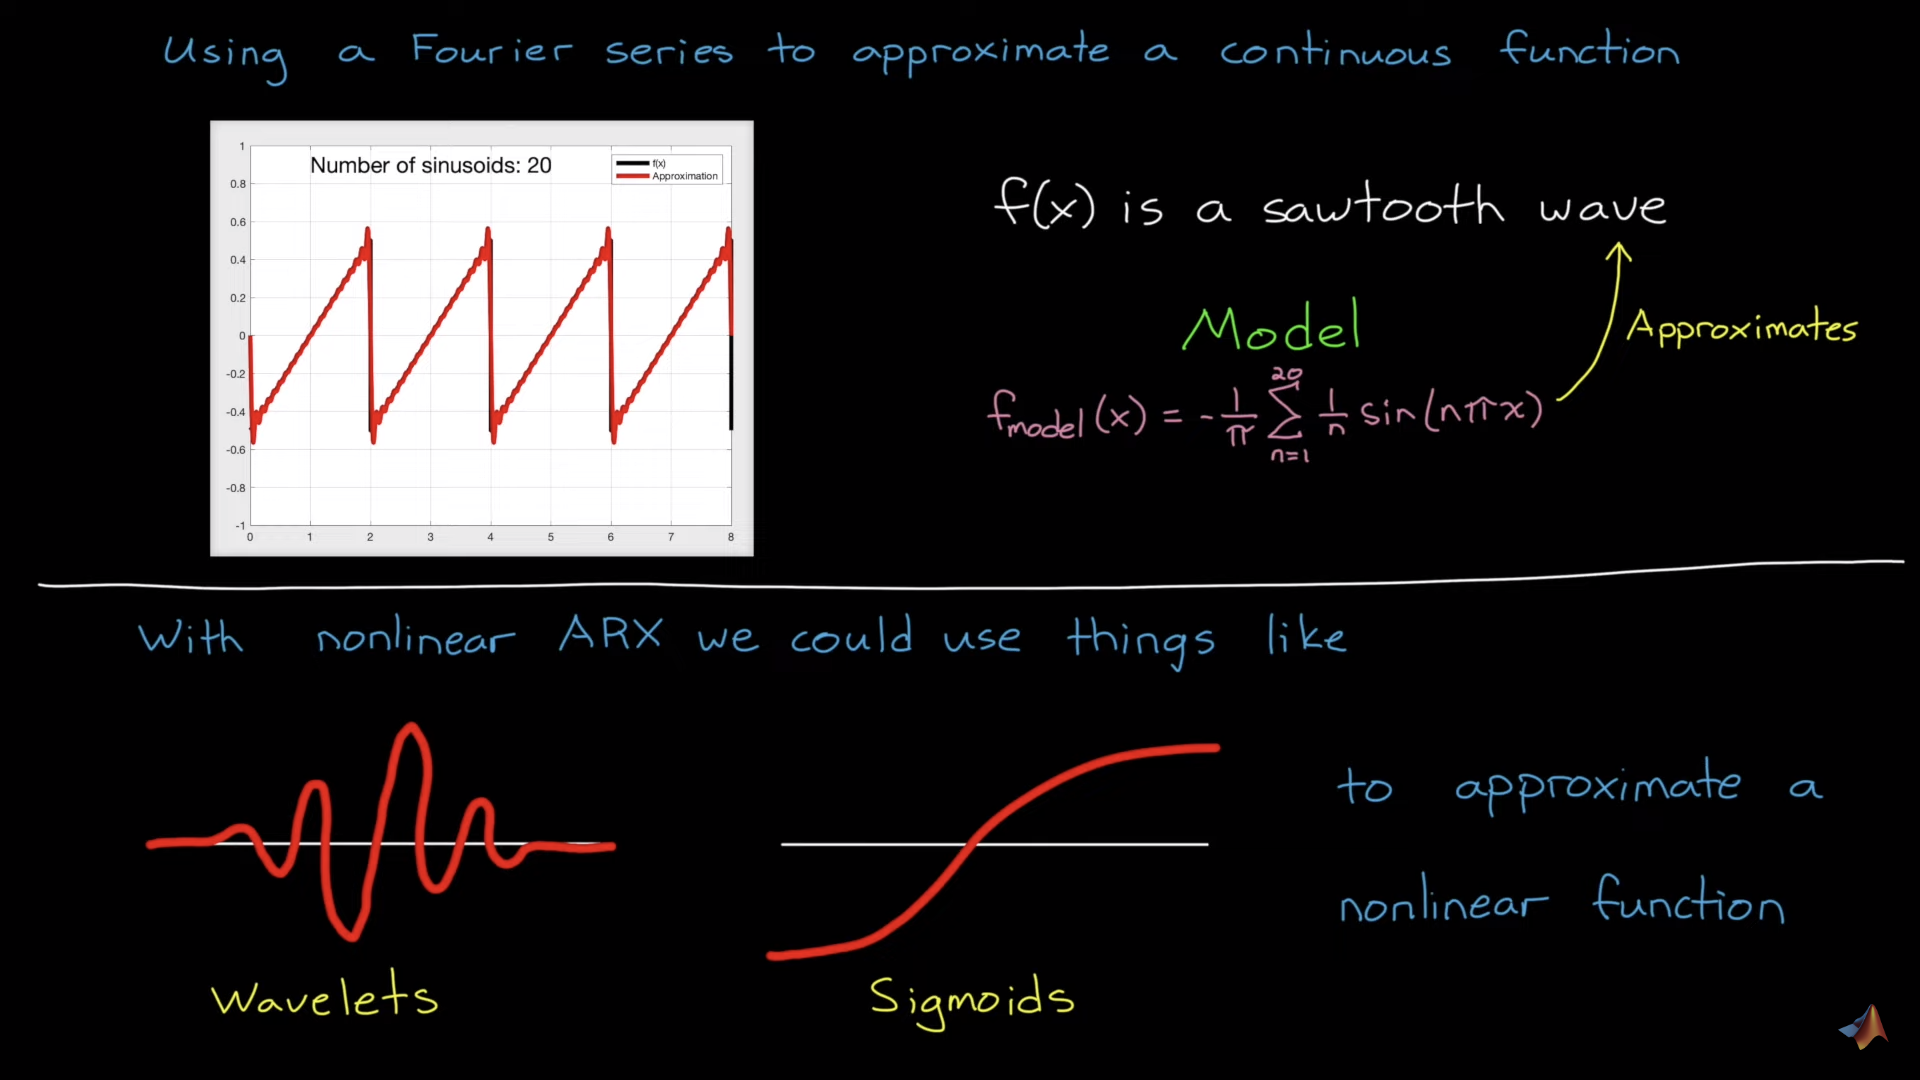

% if SigmoidNetwork does not work, try Gaussian, Wavelet, ...etc.
NL4_structure = idnlarx(z1.OutputName, z1.InputName, R, idSigmoidNetwork);
% idGaussianProcess requires Statistics and Machine Learning Toolbox
% NL4_structure = idnlarx(z1.OutputName, z1.InputName, R, idGaussianProcess);
% NL4_structure = idnlarx(z1.OutputName, z1.InputName, R, idWaveletNetwork);

% Replace Linear model
NL4_structure.OutputFcn.LinearFcn.InputProjection = mw2.OutputFcn.LinearFcn.InputProjection;
NL4_structure.OutputFcn.LinearFcn.Value = mw2.OutputFcn.LinearFcn.Value;
% don't let the fit changing the linear weights
NL4_structure.OutputFcn.LinearFcn.Free(:) = false;

### Fit the model to the data

opt = nlarxOptions('SearchMethod','lsqnonlin');
opt.SearchOptions.MaxIterations = 100;
mw4 = nlarx(z1, NL4_structure, opt);

## Model validation

Review the model

mw4.OutputFcn

ans = Sigmoid Network
Inputs: y1(t-1), y1(t-2), u1(t), u1(t-1), u1(t-2), sqrt(y1(t-1))
Output: y1(t)

 Nonlinear Function: Sigmoid network with 10 units
 Linear Function: fixed to [0.136 0.0249 0.0986 0.0544 0.013 -0.000432]
 Output Offset: initialized to 0.138

          Inputs: {'y1(t-1)'  'y1(t-2)'  'u1(t)'  'u1(t-1)'  'u1(t-2)'  'sqrt(y1(t-1))'}
         Outputs: {'y1(t)'}
    NonlinearFcn: '

Examine the result by comparing the response of the model `mw2` to the measured output in the dataset `z1`.

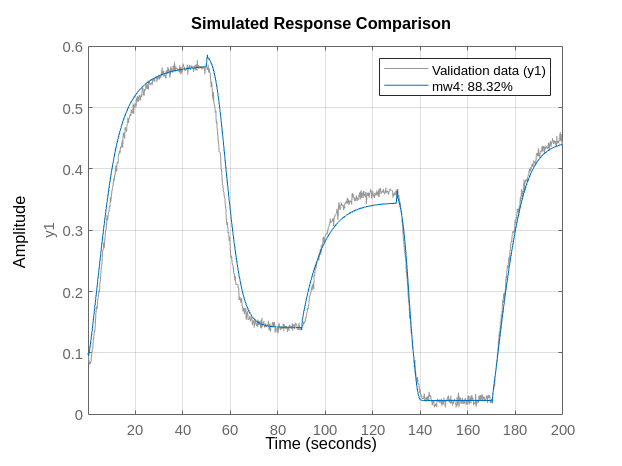

% training set
compare(z1,mw4);
grid on

Examine the result by comparing the response of the model `mw2` to the validation dataset `z2`.

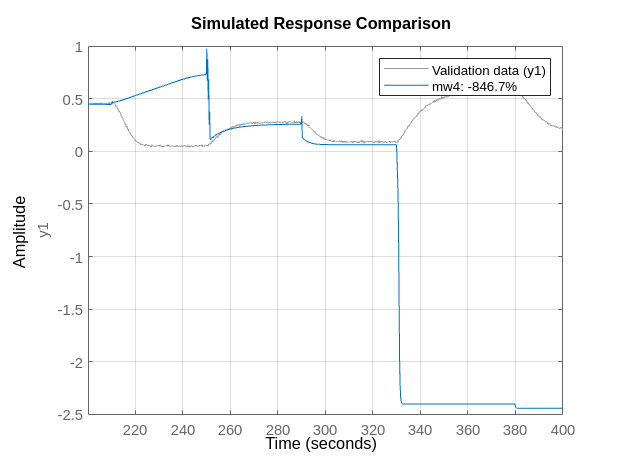

% validation set
compare(z2,mw4);
grid on

Examine the result by comparing the response of the model `mw2` to the validation dataset `z3`.

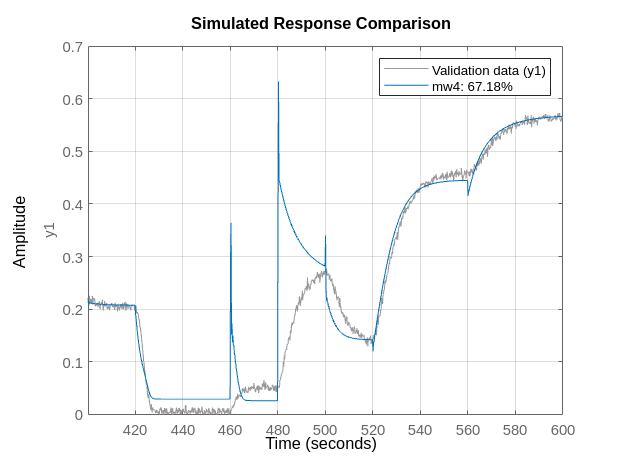

% validation set
compare(z3,mw4);
grid on